## -------------------------------------------------------------------------------

## ZAD 1 ----------------------------------------------------------------------

## -------------------------------------------------------------------------------

## Układ mechaniczny

y'' + by' + cy + dy^3 = 0

#### Krok 1

clear all;
close all;
warning('off', 'all')

syms b c d
b_d = 0.5;
c_d = 0.6;

x = sym('x',[1 2])

$$x = \left(\begin{array}{cc} x_{1} & x_{2} \end{array}\right)$$


%Krok 1

mech_syms = [x(1)*(-2 - b*x(2));
             x(2)*(8 + c * x(1))]

$$mech\_syms = \left(\begin{array}{c} -x_{1}\,\left(b\,x_{2}+2\right)\\ x_{2}\,\left(c\,x_{1}+8\right) \end{array}\right)$$


mech_syms_fun_wrap = matlabFunction(subs(mech_syms, [b c], [b_d c_d]))

mech_syms_fun_wrap = function_handle with value:
    @(x1,x2)[-x1.*(x2./2.0+2.0);x2.*(x1.*(3.0./5.0)+8.0)]



mech_syms_jac = jacobian(mech_syms, x)

$$mech\_syms\_jac = \left(\begin{array}{cc} -b\,x_{2}-2 & -b\,x_{1}\\ c\,x_{2} & c\,x_{1}+8 \end{array}\right)$$


assume(d, 'positive');
Sx_dpos = solve(mech_syms);
[Sx_dpos.x1, Sx_dpos.x2];

#### Krok 2

mech_sym_jac_eq = [];
mech_sym_jak_eq_eig = [];
for n = 1:numel(Sx_dpos.x1)
    jac_eq = subs(mech_syms_jac, [x(1), x(2)], [Sx_dpos.x1(n), Sx_dpos.x2(n)]);
    mech_syms_jac_eq(:, :, n) = jac_eq;
    [D, V]  = eig(jac_eq);
end
mech_syms_jac_eq;

#### Krok 3-4

xlim = [-5, 5];
ylim = [-5, 5];
sens = 0.1;
tspan = linspace(0, 10, 100);

x1_eq = subs(Sx_dpos.x1, [b, c], [b_d, c_d])

$$x1\_eq = \left(\begin{array}{c} 0\\ -\frac{40}{3} \end{array}\right)$$

x2_eq = subs(Sx_dpos.x2, [b, c], [b_d, c_d])

$$x2\_eq = \left(\begin{array}{c} 0\\ -4 \end{array}\right)$$

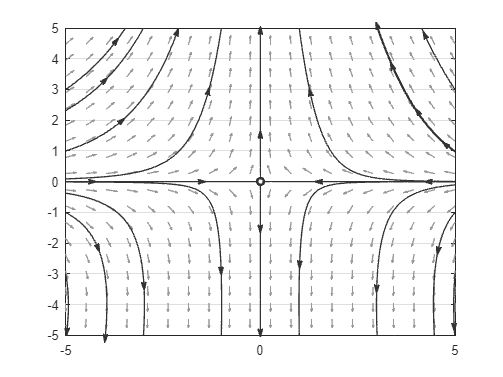


odefun = @(t, x) mech_syms_fun_wrap(x(1), x(2));
plotpp(odefun, xlim = xlim, ylim = ylim)
hold on
x_ = [];
y_ = [];


hold off

#### Krok 5

x1_eq = 0

x2_eq = 0

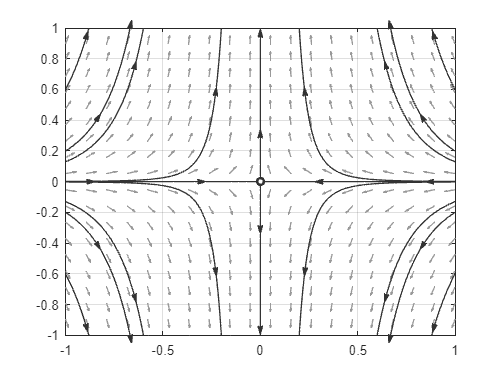

ans = logical
   0


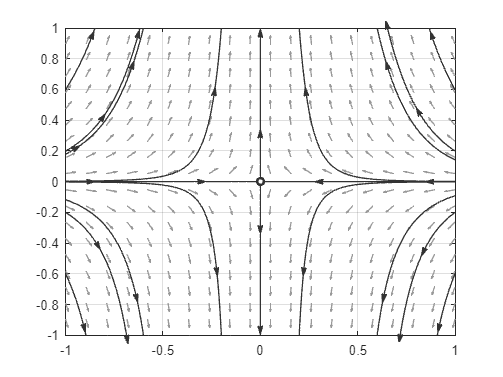

x1_eq = -13.3333

x2_eq = -4

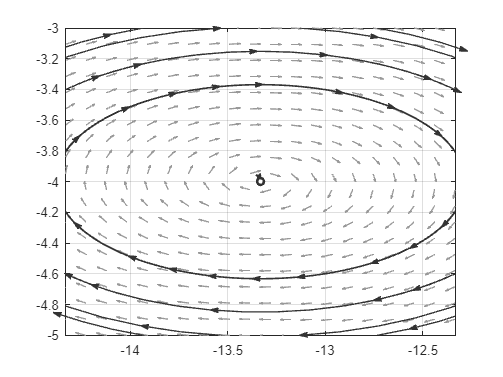

ans = logical
   0


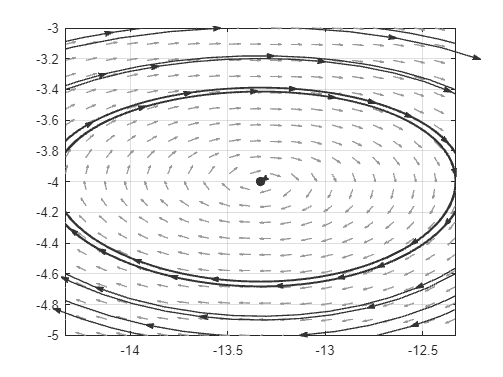

%plotpp(@(t, x) mech_syms_fun_wrap(x(1), x(2))); % plot the phase portraits
%hold on;

lin_approx_vec = [];

for n = 1:2
    x1_eq = double(subs(Sx_dpos.x1(n), [b c], [b_d c_d]))
    lin_approx = zeros([2, 2]);
    x2_eq = double(subs(Sx_dpos.x2(n), [b c], [b_d c_d]))
    x1lim = [x1_eq-1, x1_eq+1];
    x2lim = [x2_eq-1, x2_eq+1];

    if(isreal(x1_eq) && isreal(x2_eq))
    
        lin_approx = double(subs(mech_syms_jac_eq, [b, c], [b_d, c_d]));
        lin_approx = lin_approx(:, :, n);
        lin_approx_vec(:, :, n) = lin_approx;
        
        plotpp(@(t, x) lin_approx * ([x(1); x(2)] - [x1_eq; x2_eq]), xlim = x1lim, ylim = x2lim)
        q = ss(lin_approx, [0, 0; 0, 0], [0, 0; 0, 0], [0, 0; 0, 0]);
        isstable(q)

        plotpp(@(t, x) mech_syms_fun_wrap(x(1), x(2)), xlim = x1lim, ylim = x2lim);
    
    end %if
end

#### Krok 6

x0 = [0.25; 0.25];
[ t , x ] = ode45 (@( t , x)  mech_syms_fun_wrap(x(1), x(2)) , [0  10] , x0);
[ t_lin , x_lin ] = ode45 (@( t , x)  lin_approx_vec(:,:, 1) * ([x(1); x(2)] - [x1_eq; x2_eq]) , [ 0  10] , x0);

figure
subplot(2, 2, 1)
plot(t, x(:, 1));
title(["x1 układu nieliniowego"])
grid on;
subplot(2, 2, 2)
plot(t, x(:, 2))
title(["x2 układu nieliniowego"])
grid on;
subplot(2, 2, 3)
plot(t_lin, x_lin(:, 1));
title(["x1 układu liniowego"])
grid on;
subplot(2, 2, 4)
plot(t_lin, x_lin(:, 2))
title(["x2 układu liniowego"])
grid on;
filename = sprintf("mech_zmienne_stanu_x0%d.png", x0);
saveas(gcf, filename);

## -------------------------------------------------------------------------------

## ZAD 2 ----------------------------------------------------------------------

## -------------------------------------------------------------------------------

syms c l m
b_d = 0.5;
c_d = 0.6;
d_d = (-0.7);
x = sym('x',[1 2])

system38_sym = [x(2);
    -9.81/l * sin(x(1)) - c/(l*m) * x(2)]

